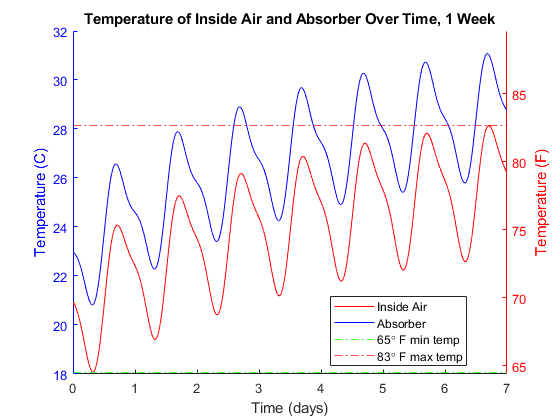

L_abs = 0.44;
L_wall = 0.029;
k_wall = 0.04;
Tspan = 7;
[t,T,T_avg] = temp(L_abs,L_wall,k_wall,Tspan*60*60*24);
plot_T(t,T)

T_avg

T_avg = 23.7463

k_wall = 0.018;
[L_sweep,L_abs_optimal,L_wall_optimal] = optimal(0.05:0.05:1,0.01:0.005:0.25,k_wall);
L_abs_optimal,L_wall_optimal

L_abs_optimal = 0.6000

L_wall_optimal = 0.0100

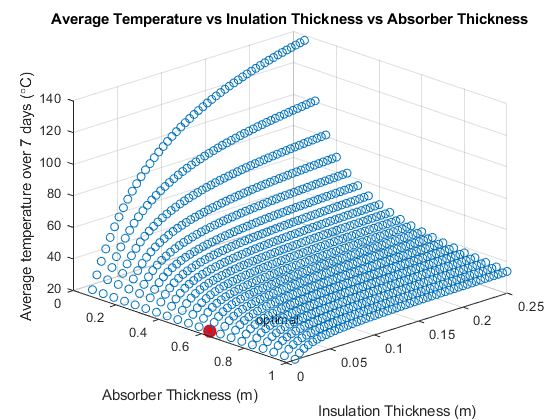

figure;
hold on

scatter3(L_sweep(:,1),L_sweep(:,2),L_sweep(:,3))
scatter3(L_abs_optimal,L_wall_optimal,20,100,'filled','r')
title('Average Temperature vs Inulation Thickness vs Absorber Thickness')
xlabel('Absorber Thickness (m)')
ylabel('Insulation Thickness (m)')
zlabel('Average temperature over 7 days (\circC)')
text(L_abs_optimal+.01,L_wall_optimal+.05,20,'optimal')
view([46 28])
grid on
hold off

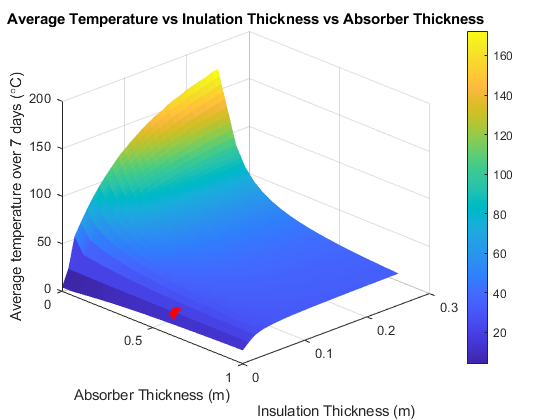


F = scatteredInterpolant(L_sweep(:,1),L_sweep(:,2),L_sweep(:,3));
[xq,yq] = meshgrid(0:.01:L_sweep(end,1),0:.01:L_sweep(end,2));
zq = F(xq,yq);

figure;
hold on
surf(xq,yq,zq,'EdgeColor','none')
scatter3(L_abs_optimal,L_wall_optimal,20,100,'filled','r')
title('Average Temperature vs Inulation Thickness vs Absorber Thickness')
xlabel('Absorber Thickness (m)')
ylabel('Insulation Thickness (m)')
zlabel('Average temperature over 7 days (\circC)')
text(L_abs_optimal+.01,L_wall_optimal+.05,20,'optimal')
view([46 28])
grid on
colorbar
hold off

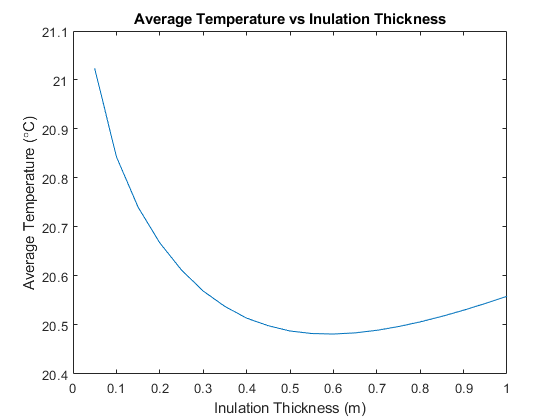

[~, i] = unique(L_sweep(:,1));
abs = [L_sweep(i,1), L_sweep(i,3)];
[~, i] = unique(L_sweep(:,2));
wall = [L_sweep(i,2), L_sweep(i,3)];
figure;
plot(abs(:,1),abs(:,2));
title('Average Temperature vs Inulation Thickness')
xlabel('Inulation Thickness (m)')
ylabel('Average Temperature (\circC)')

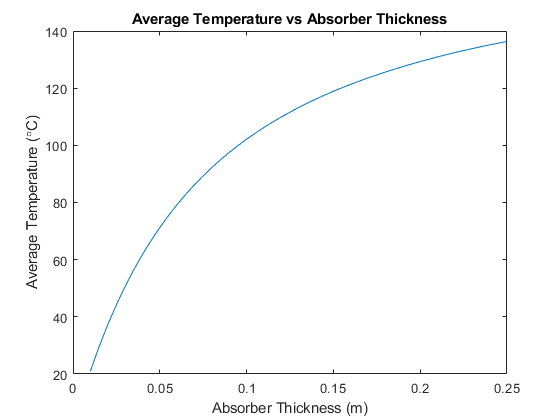

figure;
plot(wall(:,1),wall(:,2));
title('Average Temperature vs Absorber Thickness')
xlabel('Absorber Thickness (m)')
ylabel('Average Temperature (\circC)')